# Polinomios de interpolación en el análisis de temperatura

T = readmatrix('data.csv','Range','C12:C730')';
t = (0:1:length(T)-1);
GraficaGeneral(T, t); hold off;

opcion = input('¿Usted tiene conocimiento del proyecto? Sí/No: ', 's');

if strcmp(opcion, 'Sí')
    hora = input("Ingresa la hora del día a analizar (0-23): ");
    grado = input("Ingresa el grado del polinomio aproximante: ");
else
    hora = 12;
    grado = 1;
    fprintf('Hora por defecto: %d\n', hora)
    fprintf('Grado de polinomio de mínimos cuadrados por defecto: %d\n', grado)
end

Hora por defecto: 12


Grado de polinomio de mínimos cuadrados por defecto: 1


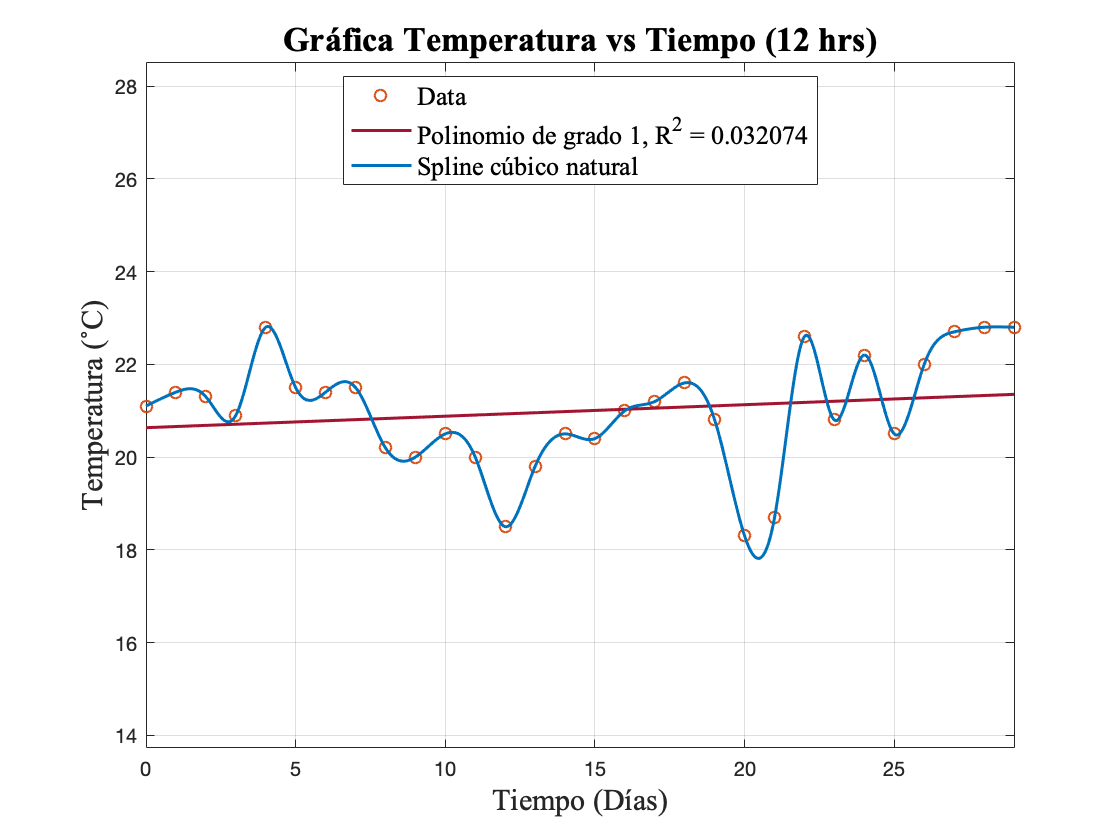


[t, T, Sx, P] = GraficaSpline(T, hora+1, grado);
hold off

## 
$$S_i \left(x\right)={a\left(x-x_i \right)}^3 +{b\left(x-x_i \right)}^2 +c\left(x-x_i \right)+d\;\;\;\;\forall \;\;\;\;i=0,1,\ldotp \ldotp \ldotp ,N-1$$


Spline Cúbico Natural:

disp(Sx)

    i     (x-x[i])        a             b            c         d       [x(i), x(i+1)]  
    __    ________    __________    _________    _________    ____    _________________

     0    "(x-0)"      -0.023477            0      0.32348    21.1    "si x ∈ [0, 1]"  
     1    "(x-1)"       -0.28262    -0.070431      0.25305    21.4    "si x ∈ [1, 2]"  
     2    "(x-2)"         1.2539     -0.91828     -0.73566    21.3    "si x ∈ [2, 3]"  
     3    "(x-3)"        -2.1331       2.8435       1.1896    20.9    "si x ∈ [3, 4]"  
     4    "(x-4)"         1.7786      -3.5559      0.47726    22.8    "si x ∈ [4, 5]"  
     5    "(x-5)"       -0.58139         1.78      -1.2986    21.5    "si x ∈ [5, 6]"  
     6    "(x-6)"       -0.45309     0.035849      0.5172

Graficamos el polinomio interpolante de Newton:

GraficaNewton(t, T, length(t)/2);

Gráfica de aproximación para los primeros días de diciembre:

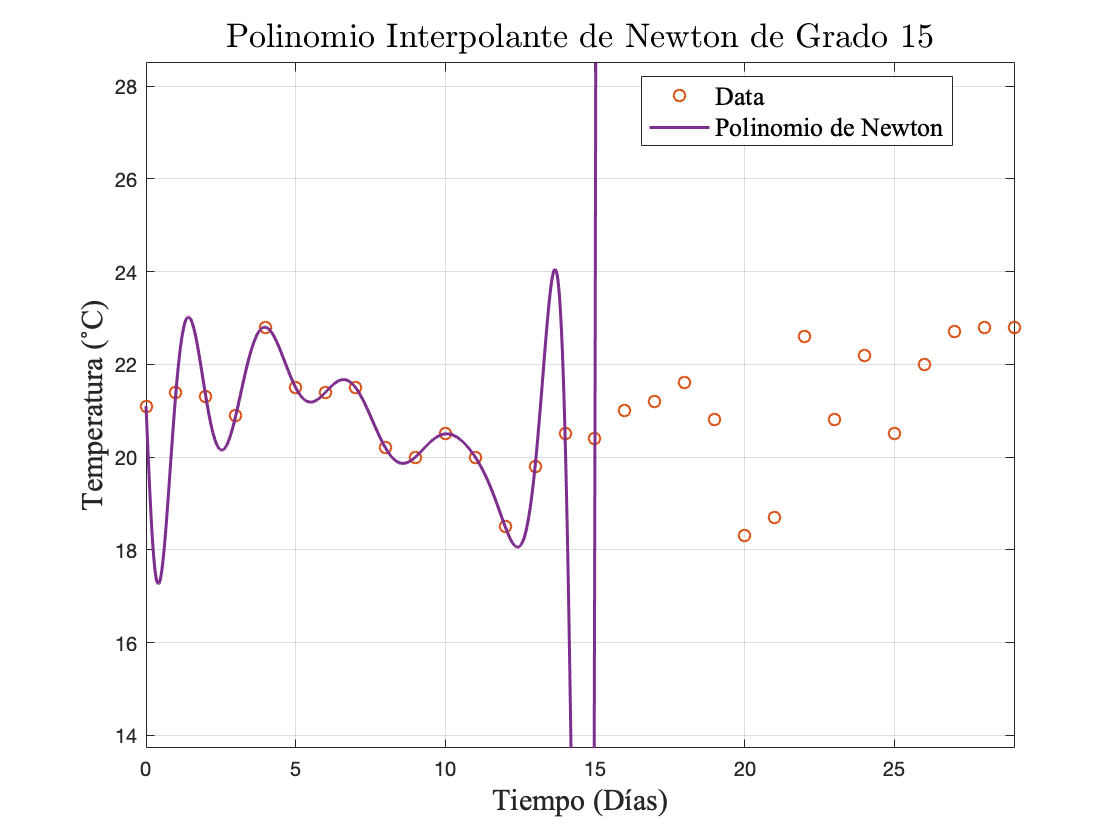

dias = input('Ingrese la cantidad de días de diciembre para estimar: ');

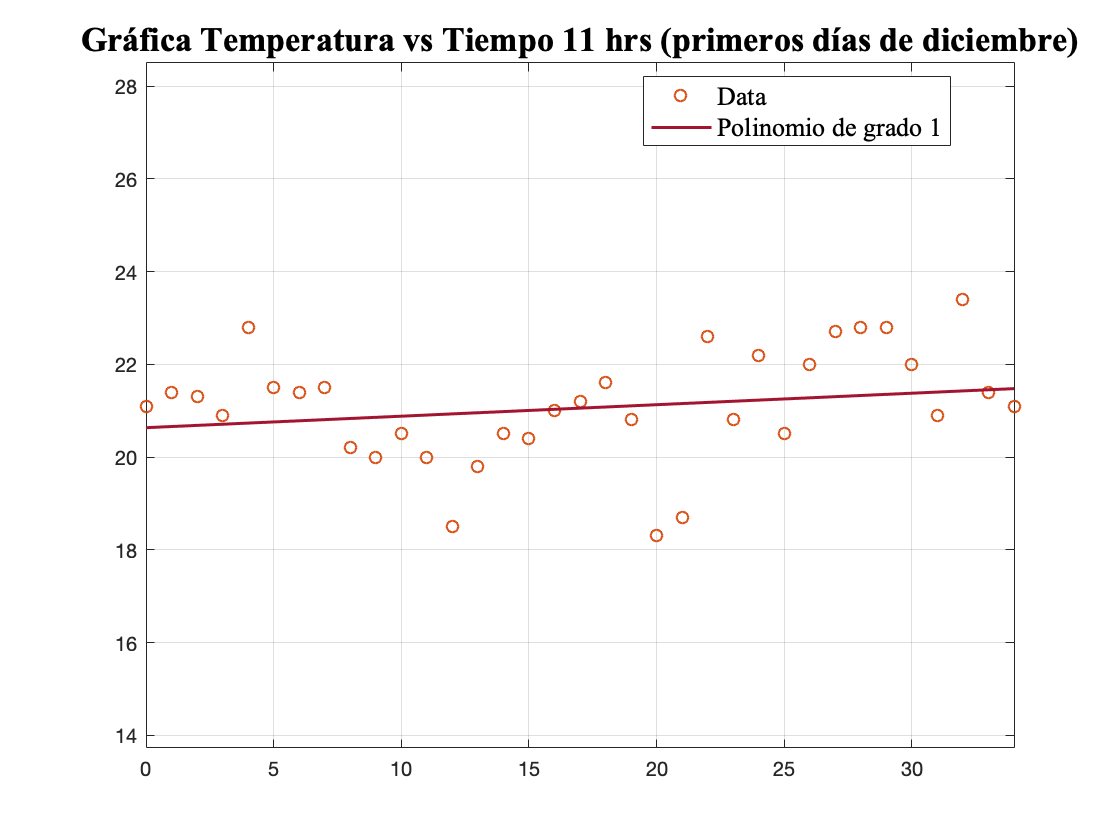

GraficaConDiciembre(T, hora, P, grado, dias);

Pt = polyval(P, (31:1:(30+dias)));
Error = abs(Pt - TDiciembre(1:dias))